Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\User\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" v3.7.9 to the path - new version 3.8.1 available
EEGLAB: adding "ICLabel" v1.4 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.8 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v5.0 (see >> help eegplugin_dipfit)
EEGLAB: adding "firfilt" v2.7.1 (see >> help eegplugin_firfilt)


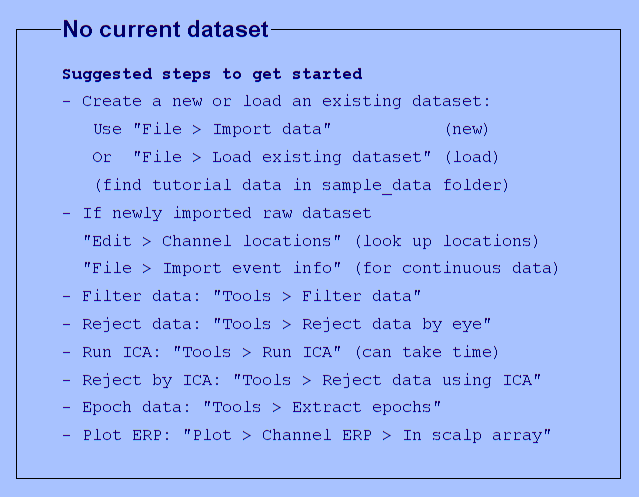

You are using the latest version of EEGLAB.


addpath 'C:\Users\User\OneDrive\Documents\githubProjects\PE_Omission-Anat\eeglab2023.0'
eeglab

import_type ='eventDetectionChan';
referenced_name =  'referenced';

input_dir_epoched = 'C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\rerefrenced';
csv_dir = 'C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\eventDetection\detected_csv';
output_dir = 'C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\eventDetection\updatedEEGLABEvents';

subs = {'08','09','10','11','13','14','15','16','17','19','20','21','23','24','25','26','27','28','29','30','31','32','33','34','35','36','37','38'};
fs = 500; %% of the eventDetection eeg files

epoch_dur = 0.5; % in sec

for sub_ind=1:size(subs,2)
    sleep_files_name_suffix = strcat('_sleep','_',referenced_name,'.set');
    output_filename = strcat(output_dir,'/sub',subs(sub_ind),'_', referenced_name, '_sleepEvents.mat');
    if isfile(output_filename)
        string(strcat('Sub_',subs(sub_ind), ' already exists in path:',  output_filename))
        continue
    end

    %% get epoched file
    try
        set_filename = strcat('s_',subs(sub_ind),'_sleep','_',referenced_name,'.set');
        eeglab_epoched =  pop_loadset(set_filename, input_dir_epoched);
    catch ME
        strcat('could not get ' ,set_filename)
        continue
    end 
    events_epoched = eeglab_epoched.event;

    sleepEvents_epoched_events = addEEGLABEvent_sleepEvents(subs(sub_ind),epoch_dur,fs,events_epoched,csv_dir);

    %% Save the new eeglab event struct
    if ~isfolder(output_dir)
        mkdir(output_dir)
    end
    save(output_filename{1},"sleepEvents_epoched_events");
end

ans = "Sub_08 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\eventDetection\updatedEEGLABEvents/sub08_referenced_sleepEvents.mat"

ans = "Sub_09 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\eventDetection\updatedEEGLABEvents/sub09_referenced_sleepEvents.mat"

ans = "Sub_10 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\eventDetection\updatedEEGLABEvents/sub10_referenced_sleepEvents.mat"

pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\rerefrenced\s_11_sleep_referenced.set ...
Reading float file 'C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\rerefrenced\s_11_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\rerefrenced\s_13_sleep_referenced.set ...
Reading float file 'C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\rerefrenced\s_13_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\rerefrenced\s_14_sleep_referenced.set ...
Reading float file 'C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\rerefrenced\s_14_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\rerefrenced\s_15_sleep_referenced.set ...
Reading float file 'C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\rerefrenced\s_15_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\rerefrenced\s_16_sleep_referenced.set ...
Reading float file 'C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\rerefrenced\s_16_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\rerefrenced\s_17_sleep_referenced.set ...
Reading float file 'C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\rerefrenced\s_17_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\rerefrenced\s_19_sleep_referenced.set ...
Reading float file 'C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\rerefrenced\s_19_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\rerefrenced\s_20_sleep_referenced.set ...
Reading float file 'C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\rerefrenced\s_20_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\rerefrenced\s_21_sleep_referenced.set ...
Reading float file 'C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\rerefrenced\s_21_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\rerefrenced\s_23_sleep_referenced.set ...
Reading float file 'C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\rerefrenced\s_23_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\rerefrenced\s_24_sleep_referenced.set ...
Reading float file 'C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\rerefrenced\s_24_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


ans = "Sub_25 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\eventDetection\updatedEEGLABEvents/sub25_referenced_sleepEvents.mat"

ans = "Sub_26 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\eventDetection\updatedEEGLABEvents/sub26_referenced_sleepEvents.mat"

ans = "Sub_27 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\eventDetection\updatedEEGLABEvents/sub27_referenced_sleepEvents.mat"

ans = "Sub_28 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\eventDetection\updatedEEGLABEvents/sub28_referenced_sleepEvents.mat"

ans = "Sub_29 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\eventDetection\updatedEEGLABEvents/sub29_referenced_sleepEvents.mat"

ans = "Sub_30 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\eventDetection\updatedEEGLABEvents/sub30_referenced_sleepEvents.mat"

ans = "Sub_31 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\eventDetection\updatedEEGLABEvents/sub31_referenced_sleepEvents.mat"

ans = "Sub_32 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\eventDetection\updatedEEGLABEvents/sub32_referenced_sleepEvents.mat"

ans = "Sub_33 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\eventDetection\updatedEEGLABEvents/sub33_referenced_sleepEvents.mat"

ans = "Sub_34 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\eventDetection\updatedEEGLABEvents/sub34_referenced_sleepEvents.mat"

ans = "Sub_35 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\eventDetection\updatedEEGLABEvents/sub35_referenced_sleepEvents.mat"

ans = "Sub_36 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\eventDetection\updatedEEGLABEvents/sub36_referenced_sleepEvents.mat"

ans = "Sub_37 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\eventDetection\updatedEEGLABEvents/sub37_referenced_sleepEvents.mat"

ans = "Sub_38 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\eventDetection\updatedEEGLABEvents/sub38_referenced_sleepEvents.mat"

function [new_epoched_event] = addEEGLABEvent_sleepEvents(sub,epoch_dur,fs,events_epoched,csv_dir)
    % Initialize new_epoched_event struct
    add_columns = {'preEpoched_filenum', ...
                    'ss_start_t','ss_end_t','ss_power',...
                    'kc_start_t','kc_end_t','kc_amp'};
    new_epoched_event = events_epoched;
    zeros = cell(1,size(events_epoched,2));
    zeros(:) = {0};
    for i=1:size(add_columns,2)
        [new_epoched_event.(add_columns{i})] = zeros{:};
    end
    
    % assosiate each event with preEpoched file
    curr_nonepoched_file = 1;
    epoched_initTime = [events_epoched.init_time];
    new_epoched_event(1).('preEpoched_filenum') = 1;
    for epoched_i=2:size(events_epoched,2)
        if epoched_initTime(epoched_i - 1) > epoched_initTime(epoched_i)
            curr_nonepoched_file = curr_nonepoched_file + 1;
        end
        new_epoched_event(epoched_i).('preEpoched_filenum') = curr_nonepoched_file;
    end

    % load ss detected events
    curr_event_filename = strcat(csv_dir,'\sub-',sub,'_SS-[4, 10, 1].csv');
    curr_ss_events = readtable(curr_event_filename{1});
    % show time in sec
    curr_ss_events.spindleStartTime = curr_ss_events.spindleStartTime / fs;
    curr_ss_events.spindleEndTime = curr_ss_events.spindleEndTime / fs;
    curr_ss_events.peakTime = curr_ss_events.peakTime / fs;
    
    % populate event table with ss details
    for epoched_i=2:size(events_epoched,2)
        % look for event in curr epoch
        eventsInEpochTime = curr_ss_events(curr_ss_events.subfile == new_epoched_event(epoched_i).('preEpoched_filenum') ...
                                & curr_ss_events.spindleStartTime <= epoched_initTime(epoched_i)+epoch_dur ...
                                & curr_ss_events.spindleEndTime >= epoched_initTime(epoched_i)...
                                , :);
        if size(eventsInEpochTime,1) > 0
            new_epoched_event(epoched_i).('ss_start_t') = eventsInEpochTime.spindleStartTime(1) - epoched_initTime(epoched_i);
            new_epoched_event(epoched_i).('ss_end_t') = eventsInEpochTime.spindleEndTime(1) - epoched_initTime(epoched_i) ;
            new_epoched_event(epoched_i).('ss_power') = eventsInEpochTime.PowerSP(1);
        end
    end
    
    % load kcomp detected events
    curr_event_filename = strcat(csv_dir,'\sub-',sub,'_KComp.csv');
    curr_kcomp_events = readtable(curr_event_filename{1},'VariableNamingRule','preserve');
    % show time in sec
    curr_kcomp_events.pos_i = curr_kcomp_events.pos_i / fs;
    curr_kcomp_events.neg_i = curr_kcomp_events.neg_i / fs;
    curr_kcomp_events.estim_duration = (curr_kcomp_events.pos_i - curr_kcomp_events.neg_i) * 2;
    curr_kcomp_events.estim_start = curr_kcomp_events.neg_i - (curr_kcomp_events.estim_duration/4);
    curr_kcomp_events.estim_end = curr_kcomp_events.pos_i + (curr_kcomp_events.estim_duration/4);
    
    % populate event table with kcomp details
    for epoched_i=2:size(events_epoched,2)
        % look for event in curr epoch
        eventsInEpochTime = curr_kcomp_events(curr_kcomp_events.subfile == new_epoched_event(epoched_i).('preEpoched_filenum') ...
                                & curr_kcomp_events.estim_start <= epoched_initTime(epoched_i)+epoch_dur ...
                                & curr_kcomp_events.estim_end >= epoched_initTime(epoched_i)...
                                , :);
        if size(eventsInEpochTime,1) > 0
            new_epoched_event(epoched_i).('kc_start_t') = eventsInEpochTime.estim_start(1)- epoched_initTime(epoched_i);
            new_epoched_event(epoched_i).('kc_end_t') = eventsInEpochTime.estim_end(1) - epoched_initTime(epoched_i);
            new_epoched_event(epoched_i).('kc_amp') = eventsInEpochTime.power(1);
        end
    end
end